clear all, close all, clc

## Prob-5.3b

syms LOCA CFS_F HW_F HX_F MDP1_F MDP2_F OP_F        % Defining Basic Events

Now, let's look at the following Fault Tree built in SAPHIRE

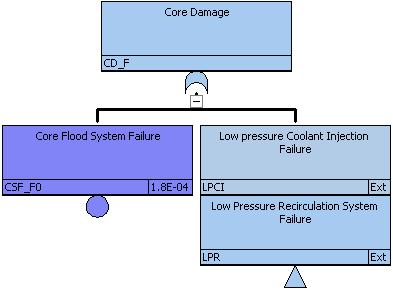

Here,

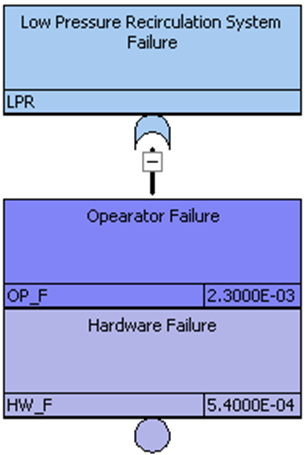  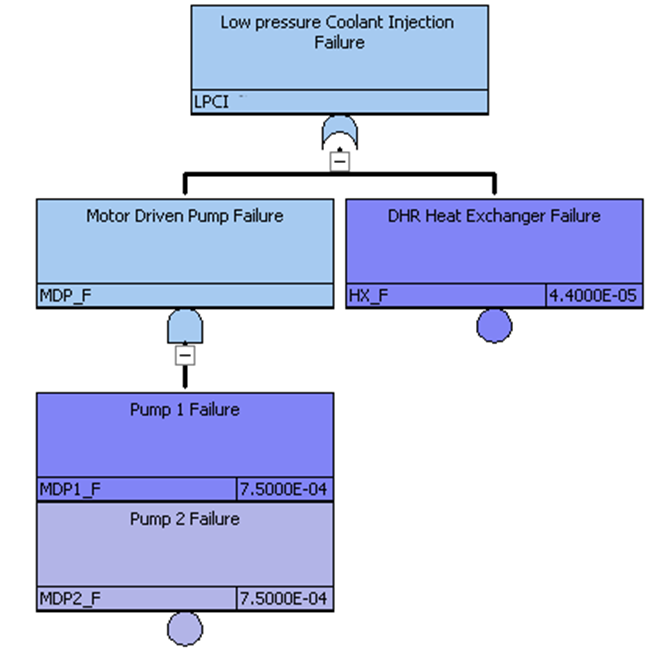

LPR_F = OP_F + HW_F

$$LPR\_F = {\mathrm{HW}}_{F}+{\mathrm{OP}}_{F}$$

LPCI_F = (MDP1_F * MDP2_F) + HX_F

$$LPCI\_F = {\mathrm{HX}}_{F}+{\mathrm{MDP}}_{1,F}\,{\mathrm{MDP}}_{2,F}$$

CD_F = LPCI_F + LPR_F + CFS_F

$$CD\_F = {\mathrm{CFS}}_{F}+{\mathrm{HW}}_{F}+{\mathrm{HX}}_{F}+{\mathrm{OP}}_{F}+{\mathrm{MDP}}_{1,F}\,{\mathrm{MDP}}_{2,F}$$

Now, if LOCA is introduced, we have, the cut sets

MCS = CD_F * LOCA

$$MCS = \mathrm{LOCA}\,\left({\mathrm{CFS}}_{F}+{\mathrm{HW}}_{F}+{\mathrm{HX}}_{F}+{\mathrm{OP}}_{F}+{\mathrm{MDP}}_{1,F}\,{\mathrm{MDP}}_{2,F}\right)$$

Now, let's associate the following frequency withthe minimal cut-set.

LOCA = 3e-4;            % LOCA; 1/y
CFS_F = 1.8e-4;         % core flooding failure; y^-1
HW_F = 5.4e-4;          % hardware failure
HX_F = 4.4e-5;          % DHR Heat exchanger failure
MDP1_F = 7.5e-4;        % pump 1 failure 
MDP2_F = MDP1_F;        % pump 2 failure
OP_F = 2.3e-3;          % operator failure

Then we have-

MCS = eval(MCS)

MCS = 9.1937e-07

(Ans)